# Plant

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.

clearvars -except commonPath
plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Input Signals1

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
clear inputPath latestSlow latestFast
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Globals

delta_t = t(2)-t(1);
delta_pureSinTime = pureSinTime(2)-pureSinTime(1);
KpStatic = 50;
KiStatic = 1000;
tdStatic=0.04;

# Toggles

togRMSFreq = 0;
togSinglePoint = 0;
megaSweep = 1;  
figurePath = strcat(commonPath,'\Golden Figures');

# Model

%Model Setup
tend = num2str(pureSinTime(end));
stepsize = num2str(delta_pureSinTime);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'FastRestart','off')
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize) %'SimulationMode','accelerator','SimCompilerOptimization','on'
save_system(simName)

rat_I = 4.971;

# Setting up gains for sweep

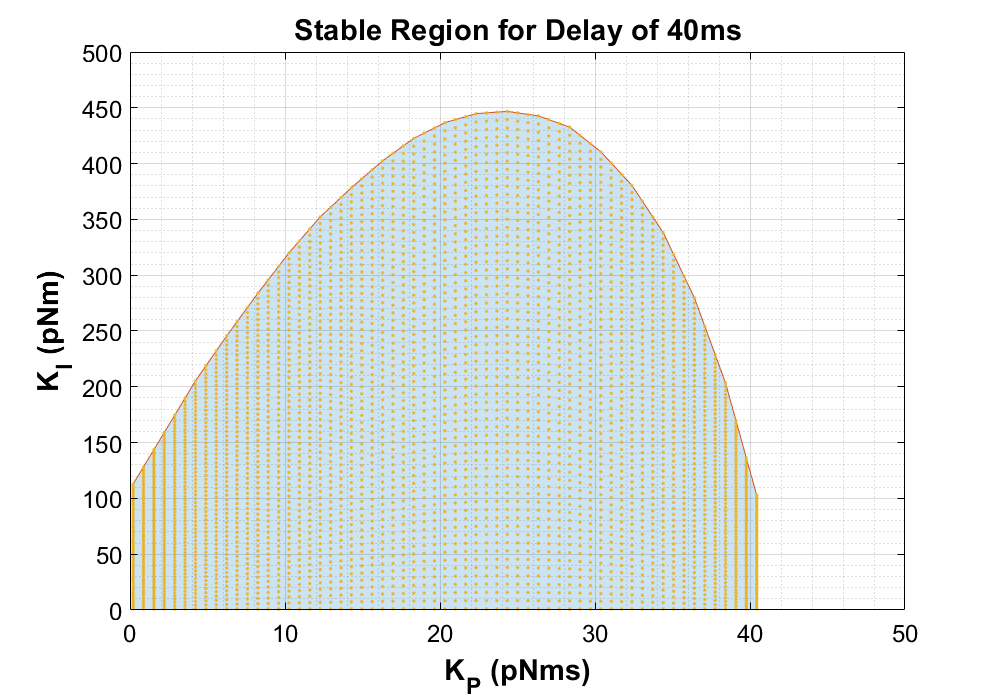

%Smooth Stability Data - Get max 04 Slice for sweeping over stable domain

slicePath = strcat(commonPath,'\Stability Sweep Data\');
latestSlice = latestTimeParse(slicePath,'04DelaySlice');
load(latestSlice)
clear slicePath latestSlice
xdata = stableSliceMax(:,1)/rat_I;
ydata = stableSliceMax(:,2)/rat_I;

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
a = area(xdata,ydata);
hold on
a.FaceAlpha = 0.2;
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('K_P (pNms)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('K_I (pNm)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title('Stable Region for Delay of 40ms','FontName','Helvetica','FontSize',22,'FontWeight','bold')
grid on
grid minor
xlim([0 50])
ylim([0 500])

%Build Stable sampling region for Ki, Kp
Kpsize = 61;%61;
Kisize = 61;%61;
stableSweepKp = linspace(min(xdata),max(xdata),Kpsize);
maxKiInterp = interp1(xdata(2:end-3),ydata(2:end-3),stableSweepKp);
plot(stableSweepKp,maxKiInterp)

stableSweepKi = zeros(length(stableSweepKp),Kisize);
orderedPairs = zeros(Kpsize*Kisize,2);
opIndex = 1;
%Build Ki regions
for i = 1:length(stableSweepKp)
    stableSweepKi(i,:) = linspace(1,maxKiInterp(i),Kisize);
    orderedPairs(opIndex:opIndex - 1 + Kisize,1) = stableSweepKp(i)*ones(Kisize,1);
    orderedPairs(opIndex:opIndex - 1 + Kisize,2) = stableSweepKi(i,:)';
    opIndex = opIndex + Kisize;
end

plot(orderedPairs(:,1),orderedPairs(:,2),'.')


%Full region sweep
KpFull = linspace(1,501,Kpsize); %pNms
KiFull = linspace(1,3001,Kisize); %pNm        
KiFull = repmat(KiFull,Kpsize,1);

%Toggle for stable region or full region
stableOnly = 1;

Kp = [10 35];
Ki = [0 150; 0 150];

# Ridiculous Sweep (All params minus td = 0.04)

p =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×3721 double]
              YData: [1×3721 double]
              ZData: [1×0 double]

  Show all properties


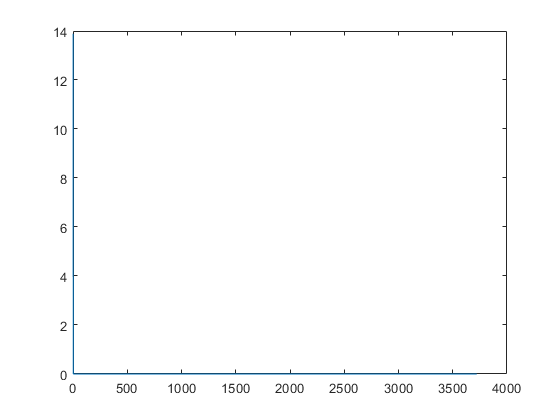

if megaSweep == 1  
    set_param(simName,'StopTime',num2str(pureSinTime(end)),'FixedStep',num2str(pureSinTime(2) - pureSinTime(1))...
        ,'FastRestart','on')
    save_system(simName)
    
    td = 0.04;
    [nump,denp]=padeWrap(td);
    d_tf = tf(nump,denp);  
    if stableOnly == 0
        Kp = KpFull;
        Ki = KiFull;
    else
        Kp = stableSweepKp;
        Ki = stableSweepKi;
    end

    switchThresh = 0:.002:0.1;
    decimationFactor = 5;
    pureSinDecimate = pureSin(5:decimationFactor:end, :);
    sinfreqsDecimate = sinfreqs(5:decimationFactor:end); 
     
    innerSize = length(Kp)*length(Ki)*length(switchThresh);
    tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
    
    %FFT Params
    Fs = 1/(pureSinTime(2)-pureSinTime(1));
    N = 10000;   
    
    
    emptyarray = -1000*ones(1,length(pureSinTime));
    hybridStruct = repmat(struct('switchThresh',-1,'hybridOut',emptyarray,'hFit',emptyarray,'hGain',-1,'hPhase',-1,...
        'hError',-1,'hFitSAE',-1,'hSAE',-1,'hIE',-1),1,length(switchThresh));
    fullStruct = struct('Kp',-1,'Ki',-1,'inputFreq',-1,'smoothOut',emptyarray,'sGain',-1,'sPhase',-1,'sError',-1,'sSAE',-1,'sIE',-1,...
        'hybridInfo',hybridStruct);
    sweepData = repmat(fullStruct,size(Ki,2),size(pureSinDecimate,1));
    
    emptySinglePoint = repmat(fullStruct,1,length(sinfreqsDecimate));
    
    ets = zeros(1,length(Kp)*size(Ki,2));
    iter = 1;
    iters = 1:1:length(Kp)*size(Ki,2);
    remaining = length(Kp)*size(Ki,2); 
    figure
    p = plot(iters,ets)
    p.XDataSource = 'iters';
    p.YDataSource = 'ets';
    et=0;
    for i = 1:length(Kp)
        for j = 1:size(Ki,2)
            tic
            sweepData(j,:) = simTrackSmoothPrefill(Kp(i),Ki(i,j),d_tf,G_plant,pureSinDecimate,pureSinTime,sinfreqsDecimate,...
                emptySinglePoint,Fs,N,tLimSet,simName,switchThresh,td);
            
            et = toc;
            ets(iter) = et;
            remaining = remaining-1;
            refreshdata
            drawnow
            iter = iter + 1;
        end
        
        basepath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp');
        savePath = genFileName(basepath,strcat('megaSweep_',num2str(i)));
        save(savePath,'sweepData','Kp','Ki','switchThresh','sinfreqsDecimate','pureSinTime','-v7.3')
        
        sweepData = repmat(fullStruct,length(Ki),size(pureSinDecimate,1));
        
    end
    

    
%     tic
%     [hybridOut,hFit,hGain,hPhase,hError,smoothOut,sGain,sPhase,sError] = deconstruct(sweepData);
%     toc
    

end

# Single Point Hybrid / Smooth comparison

if togSinglePoint == 1
    
   freqindex = 10;
   Kp = KpStatic;
   Ki = KiStatic;
   td =tdStatic;
   switchThresh = 0.5;
   T_lim_up = inf;
   T_lim_low = -inf;
   [smoothOut10, hybridOut10] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\lowgainlowfreq')
%    export_fig (savePath,'-eps')
    
    freqindex =50;
    [smoothOut80, hybridOut80] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\lowgainhighfreq')
%    export_fig (savePath,'-eps')
    
    freqindex = 30;

    [smoothOut60, hybridOut60] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\highgainmedfreq')
%    export_fig (savePath,'-eps')
    
end

# RMSE as a function of frequency and switching threshold

if togRMSFreq == 1  
    %First, the smooth system using lsim
    Kp = 3:1:10;
    for j = 1:length(Kp)
        Ki = KiStatic;
        td =tdStatic;
        [~,smoothRMSE] = simRMSE(Kp(j),Ki,td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        [~,hybridInfRMSE] = simRMSE(Kp(j),Ki,td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            [~,hybridTempRMSE] = simRMSE(Kp(j),Ki,td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp(j),Ki,switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp(j)),'_Ki_',num2str(Ki),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
    
        Ki = 1:1:10;
    for j = 1:length(Ki)
        Kp = KpStatic;
        td =tdStatic;
        [~,smoothRMSE] = simRMSE(Kp,Ki(j),td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        [~,hybridInfRMSE] = simRMSE(Kp,Ki(j),td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            [~,hybridTempRMSE] = simRMSE(Kp,Ki(j),td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp,Ki(j),switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp),'_Ki_',num2str(Ki(j)),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
end